# Estimation Theory : Assignment 3

### Part a)

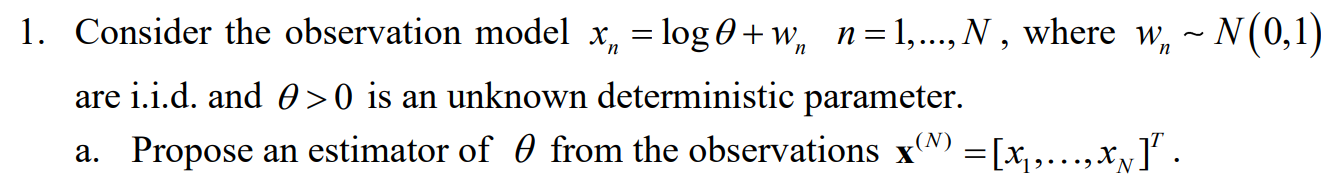

#### We simulate the statistical model of the data samples

- We choose the value of theta randomly to see that the estimator works for all values of theta but it is deterministic for the rest of the simulation.

- We add iid samples of random GWN.

clear ; clc ; clf ;

w_ = @(N) randn(1,N) 

w_ = function_handle with value:
    @(N)randn(1,N)



M = 8 ;

theta = ceil(rand()*M)

theta = 3


x_ = @(N,theta) log(theta) + w_(N)

x_ = function_handle with value:
    @(N,theta)log(theta)+w_(N)


#### We derive the ML estimator

We will build the estimator as we derived in the assignment as the sample mean:


$$\hat{\theta \;} \left(\underline{\;x} \right)=\exp \left\lbrack \frac{1}{N}\;\sum_{i=1}^N x_i \right\rbrack =e^{\bar{x} } \;$$


hat_theta_ = @(N,theta) exp(mean(x_(N,theta)));

#### We visuallize the results

We plot the distribution of result and see that we indeed got a mean of a normal distribtution as expected.

We compare between the actual and estimated values of theta and also see as expected that both are strictly positive!

N = 1000;
X = x_(N,theta)

X =    -1.0099    0.8373   -0.2210    2.3410    2.3868    1.6144    1.5987    0.1737    0.7315    0.0313    2.2782    1.7442    0.6233    2.8546    1.9864    2.5422    2.7212    0.2112    1.0112    2.1765    1.5776    3.6090    1.0195    1.0936    0.5628    2.9682    0.0662    0.9544   -0.5570    2.1618    0.2667    1.3548    1.5979    1.7445    0.8655    2.7276    1.3244    0.8914    0.6585    2.4394    1.3775    1.2931    2.6917   -0.2303    3.2695    0.6833    0.3416    1.1774    0.8456    1.7887


hat_theta = hat_theta_(N,theta)

hat_theta = 3.1327

% figure ;
% histogram(X)
% title("\theta = " + num2str(theta) + ", \theta_{ML}(X) = " + num2str(hat_theta))
% xline(log(theta),"-b","log(\theta)")
% xline(log(hat_theta),"--r","log(\hat{\theta})")

### Part b)

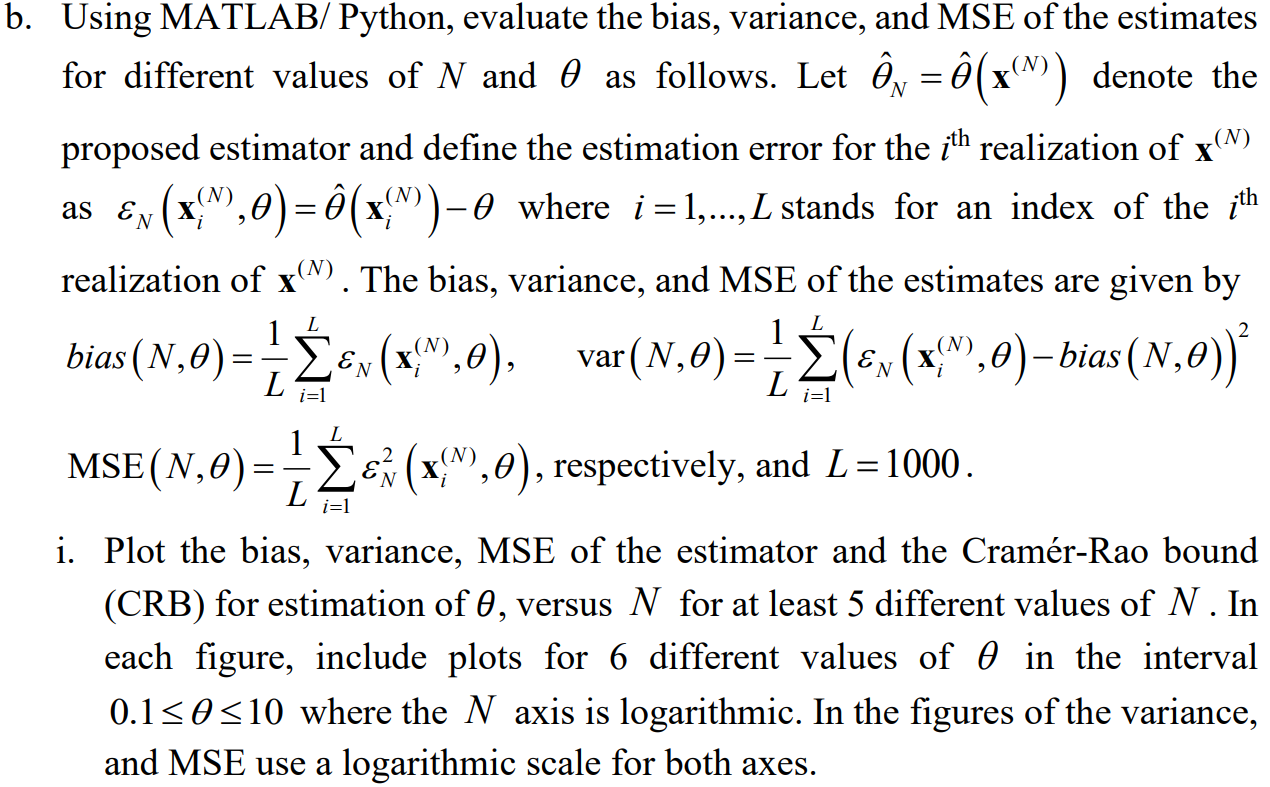

### We will create a function for simulating the evolution of the 

### **bias**,**variance**,**MSE **and the **CRB.**

#### **Estimation Error : **$\varepsilon_N \left(X_i^{\left(N\right)} ,\theta \;\right)=\hat{\theta \;} \left(X_i \right)-\theta \;\;$

epsilon_ = @(N,theta,hat_theta_) hat_theta_(N,theta) - theta;

#### **Bias : **$\textrm{bias}\left(N,\theta \;\right)=\frac{1}{L}\sum_{i=1}^L \varepsilon_N \left(X_i^{\left(N\right)} ,\theta \;\right)\;$

function output = bias(N,theta,hat_theta_,L) 
    epsilon_ = @(N,theta,hat_theta_) hat_theta_(N,theta) - theta;
    outputs = zeros(L,1);
    for i = 1 : L
        outputs(i)= epsilon_(N,theta,hat_theta_);
    end
    output = mean(outputs);
end

#### Variance :$\;\textrm{Var}\left(N,\theta \;\right)=\frac{1}{L}{\sum_{i=1}^L \left({\;\varepsilon }_N \left(X_i^{\left(N\right)} ,\theta \;\right)-\textrm{bias}\left(N,\theta \;\right)\;\right)}^2 \;$ 

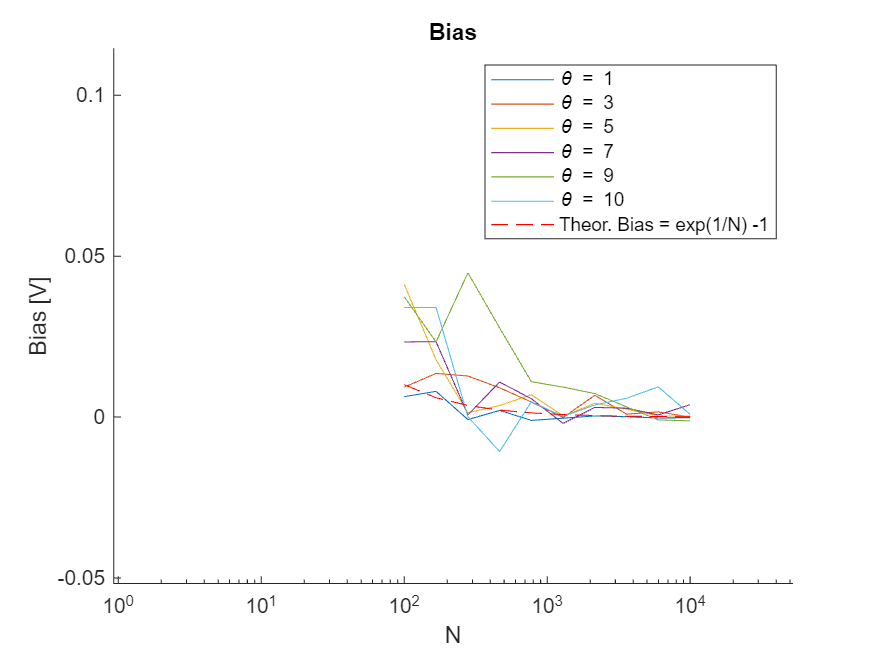

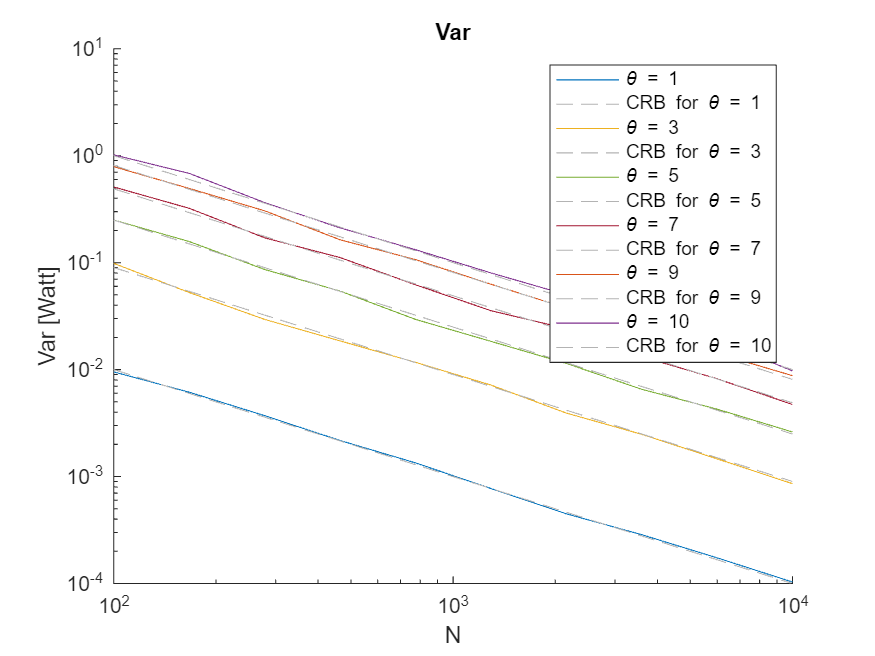

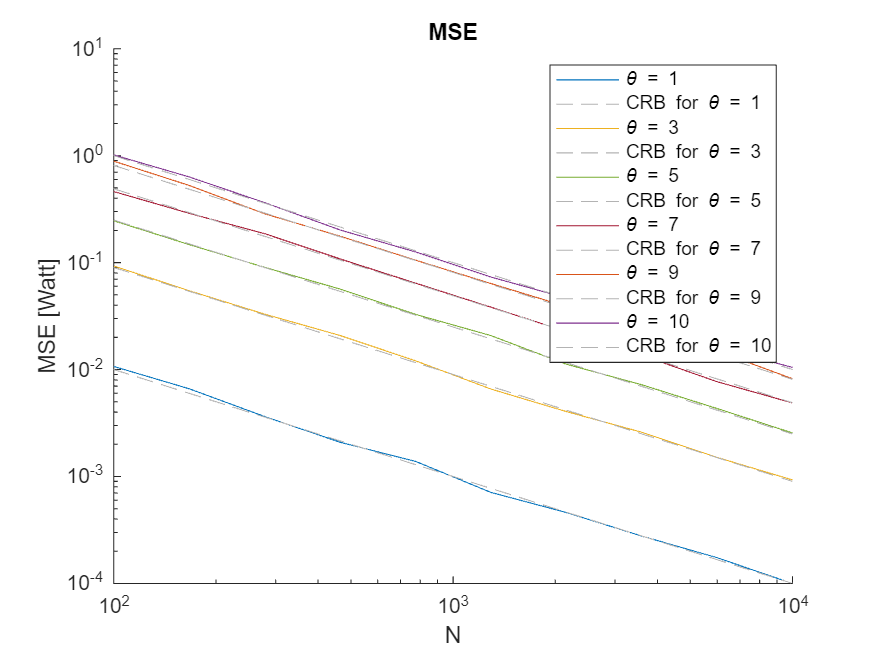

function output = variance(N,theta,hat_theta_,L) 
    epsilon_ = @(N,theta,hat_theta_) hat_theta_(N,theta) - theta;
    outputs = zeros(L,1);
    Bias = bias(N,theta,hat_theta_,L);
    for i = 1 : L     
        outputs(i)= (epsilon_(N,theta,hat_theta_) -  Bias)^2;
    end
    output = mean(outputs);
end

#### MSE :$\;\textrm{MSE}\left(N,\theta \;\right)=\frac{1}{L}{\sum_{i=1}^L {\;\varepsilon }_N \left(X_i^{\left(N\right)} ,\theta \;\right)}^2 \;$ 

function output = mse(N,theta,hat_theta_,L) 
    epsilon_ = @(N,theta,hat_theta_) hat_theta_(N,theta) - theta;
    outputs = zeros(L,1);
    for i = 1 : L     
        outputs(i)= (epsilon_(N,theta,hat_theta_))^2;
    end
    output = mean(outputs);
end

### Plotting the results :

#### Generating data :

function [Results,Theta,N_axis] = Generate_data(M,N,L,hat_theta_,bias,variance,mse)

    Theta = ceil(linspace(0.1,10,M)) ; 
    N_axis = ceil(logspace(2,4,N)) ;
    Results = zeros(N,M,3) ; 
    for j = 1:M
        theta_j = Theta(j);
        for i = 1:N
        N_i = N_axis(i);
        
        B_i_j = bias(N_i,theta_j,hat_theta_,L);
        V_i_j = variance(N_i,theta_j,hat_theta_,L);
        M_i_j = mse(N_i,theta_j,hat_theta_,L);
    
        Results(i,j,1) = B_i_j ;
        Results(i,j,2) = V_i_j ;
        Results(i,j,3) = M_i_j ;
        end
    end
end

#### Plotting as a function of $N$:

For every plot inside each figure, we fix a value of $\theta \;$and plot the bias,Var and MSE against the logarithmic N axis :

#### generating data :

M1 = 6;
N1 = 10;
L1 = 1000 ;

[Results1,Theta1,N_axis1] = Generate_data(M1,N1,L1,hat_theta_,@bias,@variance,@mse);

#### Plotting :

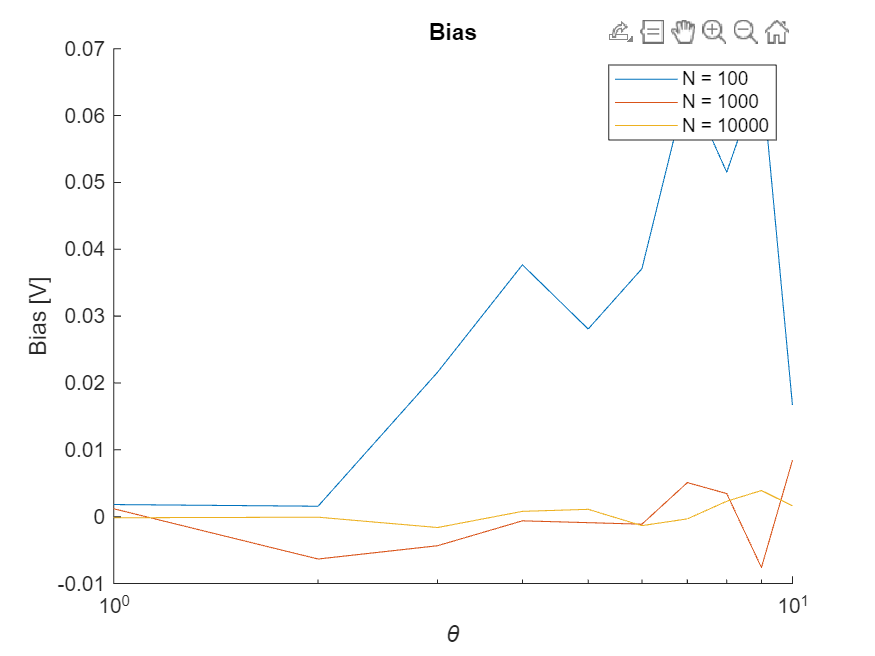

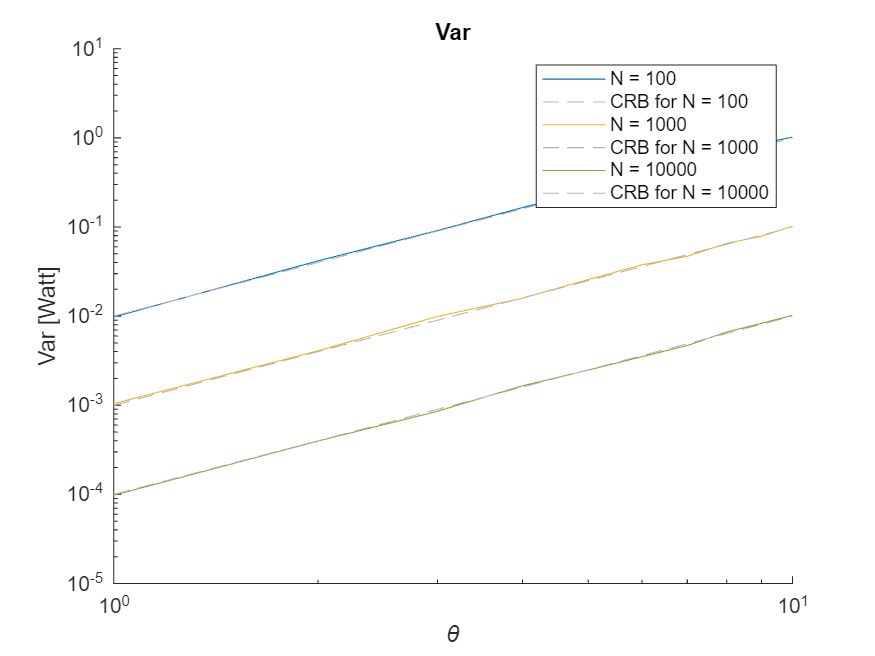

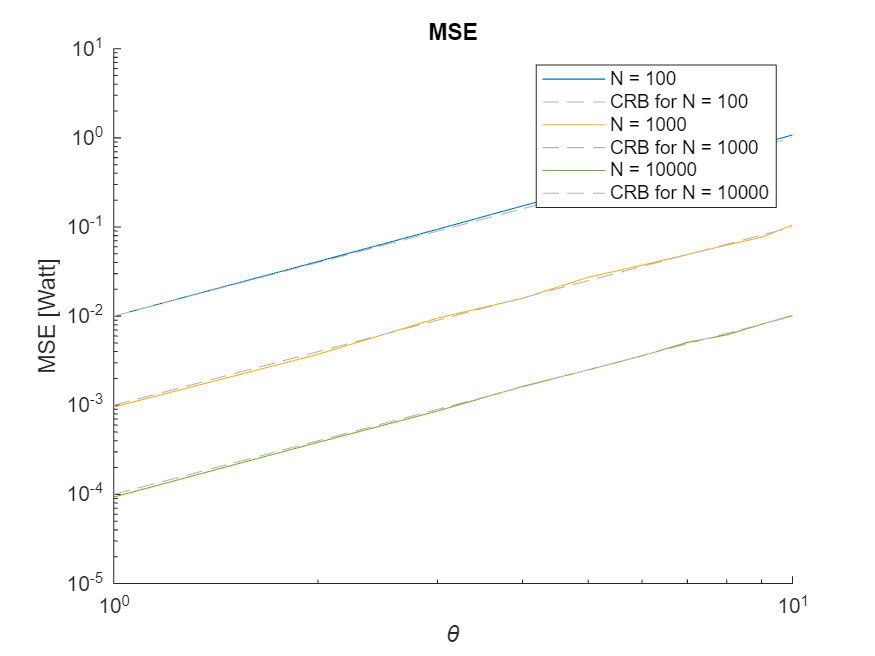

% Results : N x M x 3
% Results(:,j,k) : N x 1 x 1 
for k = 1 : 3

    figure ;
    % subplot(3,1,k);
    titles = ["Bias","Var","MSE"];
    X_Labels = ["Bias [V]","Var [Watt]","MSE [Watt]"];
    legend_values = [];
    hold on ;
    for j = 1:M1 
        theta_j = Theta1(j);
        Data = Results1(:,j,k);
        plot(N_axis1,Data)
        
        xscale log;
        title(titles(k))
        xlabel("N")
        ylabel(X_Labels(k))
        legend_values = [legend_values,"\theta = " + num2str(theta_j)];
        if k ~= 1
            plot(N_axis1,theta_j^2./N_axis1,"--",Color=[0.7,0.7,0.7])
            legend_values = [legend_values,"CRB for \theta = " + num2str(theta_j)];
        end
    end
    
    if k ~= 1 
        yscale log
    else
        plot(N_axis1,exp(1./N_axis1)-1,"--r")
        legend_values = [legend_values,"Theor. Bias = exp(1/N) -1"];
    end
    
    legend(legend_values,Interpreter="tex")
    hold off ;
end

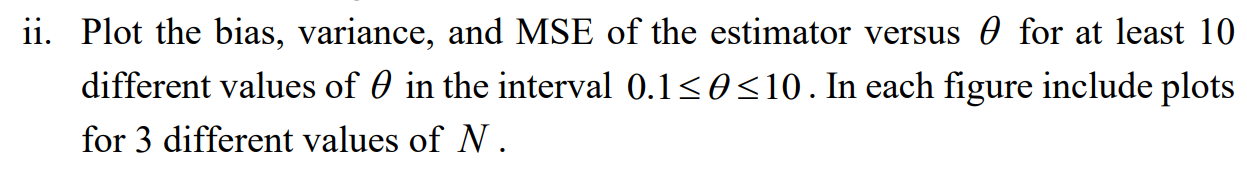

#### Plotting as a function of $\theta \;$:

For every plot inside each figure, we fix a value of $N\;$and plot the bias,Var and MSE against the linear $\theta \;$axis :

#### generating data :

M2 = 10;
N2 = 3;
L2 = 1000 ;

[Results2,Theta2,N_axis2] = Generate_data(M2,N2,L2,hat_theta_,@bias,@variance,@mse);

#### Plotting :

% Results : N x M x 3
% Results(i,:,k) : N x 1 x 1 
for k = 1 : 3
    figure ;
    titles = ["Bias","Var","MSE"];
    X_Labels = ["Bias [V]","Var [Watt]","MSE [Watt]"];
    legend_values = [];
    hold on ;
    for i = 1:N2
        N_i = N_axis2(i);
        Data = Results2(i,:,k);
        plot(Theta2,Data)
        
        xscale log;
        title(titles(k))
        xlabel("\theta")
        ylabel(X_Labels(k))
        legend_values = [legend_values,"N = " + num2str(N_i)];
        if k ~= 1
            plot(Theta2,Theta2.^2 / N_i ,"--",Color=[0.7,0.7,0.7])
            legend_values = [legend_values,"CRB for N = " + num2str(N_i)];
        end
    end
    legend(legend_values)
    if k ~= 1 
        yscale log
    end

    hold off ;
end




















